# 鲁棒跟踪控制

note4中基于误差控制引入参考信号的方法，由于系统的开环直流增益不够大而引入了稳态误差。实际上，我们很难把握系统的真实参数，设计值总会存在误差，这都将导致稳态误差。因此，我们应当提高系统的鲁棒性。

依然，设被控对象的状态空间表达为：$\[\left\{ {\begin{array}{*{20}{l}}
  {{\mathbf{\dot x}} = {\mathbf{Ax}} + {\mathbf{B}}u} \\ 
  {y = {\mathbf{Cx}} } 
\end{array}} \right.\]$，

假设引入的参考信号满足微分方程：$\[\ddot r + {\alpha _1}\dot r + {\alpha _0}r = 0\]$。

注意：这里所假设的参考信号的微分方程用于描述一类参考信号，或者说象征参考信号的阶数，且微分方程的阶次不一定为2阶。例如如果我们描述任意斜率的直线输入，可以表示为$\ddot r = 0$。

定义跟踪误差为$e=y-r$。

我们将跟踪误差的定义带入到参考信号的微分方程中，得$\[\ddot e + {\alpha _1}\dot e + {\alpha _0}e = \ddot y + {\alpha _1}\dot y + {\alpha _0}y = {\bf{C}}\left( {{\bf{\ddot x}} + {\alpha _1}{\bf{\dot x}} + {\alpha _0}{\bf{x}}} \right) = {\bf{C\xi }}\]$，

这里我们定义了$\[{\bf{\xi }} = {\bf{\ddot x}} + {\alpha _1}{\bf{\dot x}} + {\alpha _0}{\bf{x}}\]$，同样，我们还可以定义$\[\mu  = \ddot u + {\alpha _1}\dot u + {\alpha _0}u \]$。

由此，我们可以得到：$\[{\bf{\dot \xi }} = \frac{d}{{dt}}\left( {{\bf{\ddot x}} + {\alpha _1}{\bf{\dot x}} + {\alpha _0}{\bf{x}}} \right) = \frac{{{d^2}}}{{d{t^2}}}{\bf{\dot x}} + {\alpha _1}\frac{d}{{dt}}{\bf{\dot x}} + {\alpha _0}{\bf{\dot x}} = {\bf{A}}\left( {{\bf{\ddot x}} + {\alpha _1}{\bf{\dot x}} + {\alpha _0}{\bf{x}}} \right) + {\bf{B}}\left( {\ddot u + {\alpha _1}\dot u + {\alpha _0}u} \right) = {\bf{A\xi }} + {\bf{B}}\mu \]$

综上，我们可以构造误差空间(error space)为：$\[{\bf{\dot z}} = {{\bf{A}}_z}{\bf{z}} + {{\bf{B}}_z}\mu \]$

其中，$\[{\bf{\dot z}} = {\left[ {\begin{array}{*{20}{c}}
e&{\dot e}&{{{\bf{\xi }}^T}}
\end{array}} \right]^T}\]$，$\[{{\bf{A}}_z} = \left[ {\begin{array}{*{20}{c}}
0&1&{\bf{0}}\\
{ - {\alpha _0}}&{ - {\alpha _1}}&{\bf{C}}\\
{\bf{0}}&{\bf{0}}&{\bf{A}}
\end{array}} \right]\]$，$\[{{\bf{B}}_z} = \left[ {\begin{array}{*{20}{c}}
0\\
0\\
{\bf{B}}
\end{array}} \right]\]$。

取状态反馈为$\[\mu  =  - {{\bf{K}}_z}{\bf{z}} =  - \left[ {\begin{array}{*{20}{c}}
{{K_{e0}}}&{{K_{e1}}}&{{{\bf{K}}_x}}
\end{array}} \right]\left[ {\begin{array}{*{20}{c}}
e\\
{\dot e}\\
{\bf{\xi }}
\end{array}} \right]\]$，则系统的稳定只需要设置合适的$\[{\bf{K}}\]$使得$\[{{\bf{A}}_z} - {{\bf{B}}_z}{\bf{K}}\]$的特征值都具有负实部即可（转化为极点配置问题）。

我们以note4中的参数为例，设参考信号为正弦，用微分方程$\ddot r +\omega_0^2 r= 0$统一表示（即$\[{\alpha _0} =\omega_0^2\ ,\  {\alpha _1} = 0\]$），并考虑将极点配置在$\[\left[ {\begin{array}{*{20}{c}}
{ - 0.5 \pm 0.866j}&{ - 5}&{ - 6}
\end{array}} \right]\]$。利用place函数，我们得到：

set(groot,'DefaultLineLineWidth',1.5)
set(groot,'DefaultAxesFontSize',10)
set(groot,'DefaultFigureColor','w')
set(groot,'DefaultAxesFontWeight','bold')
close all
clear;clc

T = 40;
Ts = 1e-3;
stepT = 20;
rFlag = 2;
wFlag = 0;

% Plant
x0 = [0.3 0.1]';
omg0 = 2;
A = [0 1; omg0^2 0];
B = [0 1]';
C = [1 0];

% Reference Input -- Standard Case
K = [5 1];
L = [7 29]';
R = -[C 0 0]/[A-B*K B*K; zeros(2) A-L*C]*[B;0;0];
R = 1/R;

% Robust Tracking
alpha0 = 1;
alpha1 = 0;
Az = [0 1 0 0; -alpha0 -alpha1 C; zeros(2) A];
Bz = [0; 0; B];
p = [-0.5+0.866j -0.5-0.866j -5 -6];
Kz = place(Az,Bz,p);
fprintf('Ke0 = %.2f\nKe1 = %.2f\n Kx = %.2f, %.2f\n',Kz)

Ke0 = -11.00
Ke1 = 29.00
 Kx = 45.00, 12.00


对于真正施加到被控对象的控制信号$u$，我们可以从$\mu$的定义中获得：


$$\[\ddot u + {\alpha _1}\dot u + {\alpha _0}u =  - {{\bf{K}}_z}{\bf{z}} =  - {K_{e0}}e - {K_{e1}}\dot e - {{\bf{K}}_x}\left( {{\bf{\ddot x}} + {\alpha _1}{\bf{\dot x}} + {\alpha _0}{\bf{x}}} \right) \Leftrightarrow \frac{{{d^2}}}{{d{t^2}}}\left( {u + {{\bf{K}}_x}{\bf{x}}} \right) + {\alpha _1}\frac{d}{{dt}}\left( {u + {{\bf{K}}_x}{\bf{x}}} \right) + {\alpha _0}\left( {u + {{\bf{K}}_x}{\bf{x}}} \right) = {K_{e0}}e - {K_{e1}}\dot e\]$$


为了求解，不妨设临时变量$\[{x_t} = u + {{\bf{K}}_x}{\bf{x}}\]$，则上式可以化为：$\[{{\ddot x}_t} + {\alpha _1}{{\dot x}_t} + {\alpha _0}{x_t} = {K_{e0}}e - {K_{e1}}\dot e\]$

这个微分方程可以用能观标准型实现，详见model4。得到${x_t}$后只需与${{\bf{K}}_x}{\bf{x}}$做差即可得到控制信号$u$。

## 正弦信号跟踪仿真

我们对比note4所提及的Standard Case和这里描述的Robust Tracking，在正弦参考信号输入下，对两种方式进行对比：

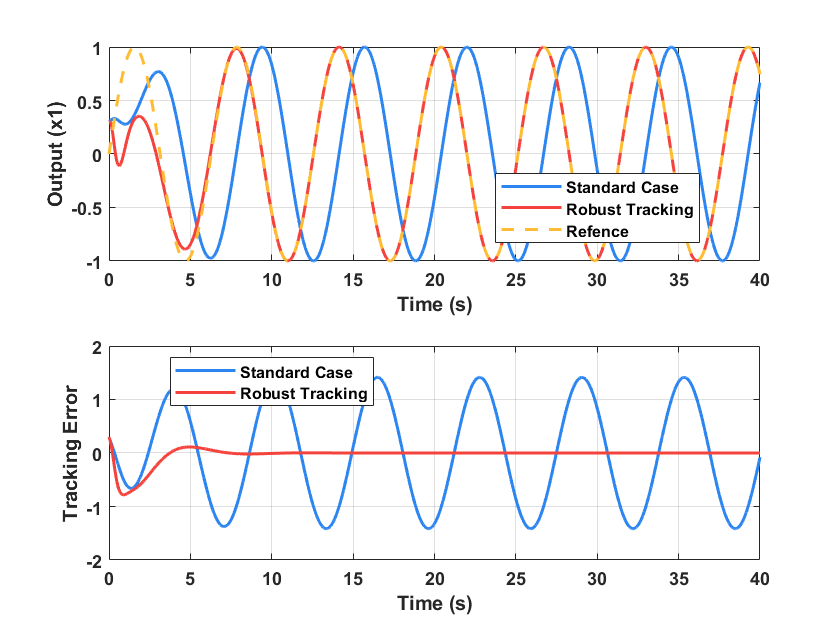

sim('model4_RobustTracking.slx')

figure
subplot(2,1,1)
plot(t,[x1(:,1) x2(:,1)])
hold on
grid on
plot(t,r,'--')
legend('Standard Case','Robust Tracking','Refence','Location','best')
xlabel('Time (s)')
ylabel('Output (x1)')
subplot(2,1,2)
plot(t,[x1(:,1)-r x2(:,1)-r])
grid on
legend('Standard Case','Robust Tracking','Location','best')
xlabel('Time (s)')
ylabel('Tracking Error')

可以看出，标准模式下输出跟随参考信号，但是具有一定的延时，且因此导致较大的跟踪误差；而基于误差的鲁棒设计则可以严格跟随参考信号，跟踪误差收敛于零。

## 同类扰动抑制

鲁棒跟踪控制除了能观使被控对象的输出严格跟随参考信号外，还能够抑制被控对象中存在的与参考信号相同类型（同一微分方程描述的）扰动。对于本次仿真，参考信号是由微分方程所描述的角频率为$\omega_0$的单频信号（不限制幅值和相位），因此我们对被控对象的两个状态分别引入同频但是不同幅度、相位的扰动$\mathbf{w}$，即被控对象变为${{\mathbf{\dot x}} = {\mathbf{Ax}} + {\mathbf{B}}u} + \mathbf{w}$，观察该方法对扰动的抑制。

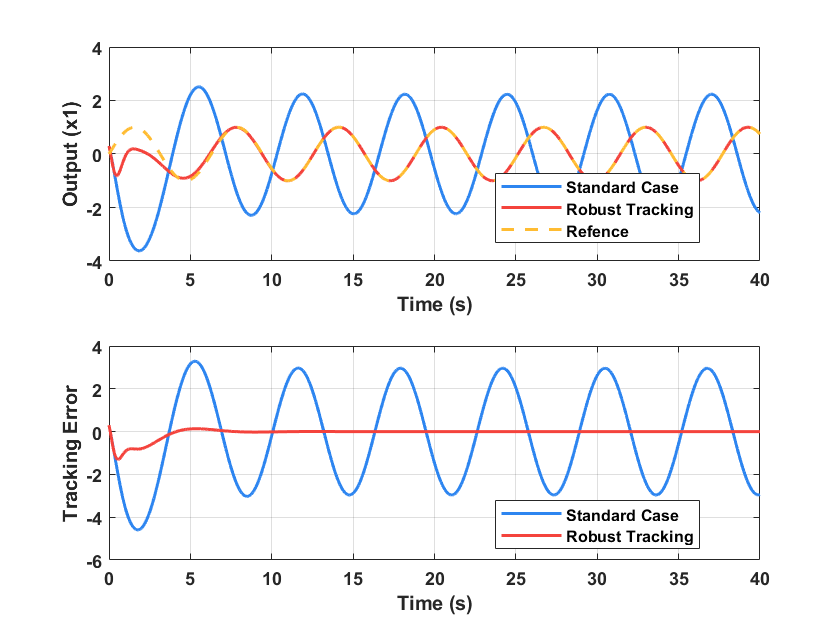

wFlag = 1;
sim('model4_RobustTracking.slx')

figure
subplot(2,1,1)
plot(t,[x1(:,1) x2(:,1)])
hold on
grid on
plot(t,r,'--')
legend('Standard Case','Robust Tracking','Refence','Location','best')
xlabel('Time (s)')
ylabel('Output (x1)')
subplot(2,1,2)
plot(t,[x1(:,1)-r x2(:,1)-r])
grid on
legend('Standard Case','Robust Tracking','Location','best')
xlabel('Time (s)')
ylabel('Tracking Error')

可见，在被控对象存在同类扰动时，被控对象的输出无法跟随由标准设计方法引入的参考，却能够收敛于鲁棒跟踪控制的参考信号。说明鲁棒跟踪控制不仅能使系统输出跟随参考信号，还能够抑制被控对象中存在的同类扰动。

## 鲁棒跟踪控制的局限

在上述设计参数不变的情况下，如果我们采用阶跃信号作为参考，两种方式的输出如下：

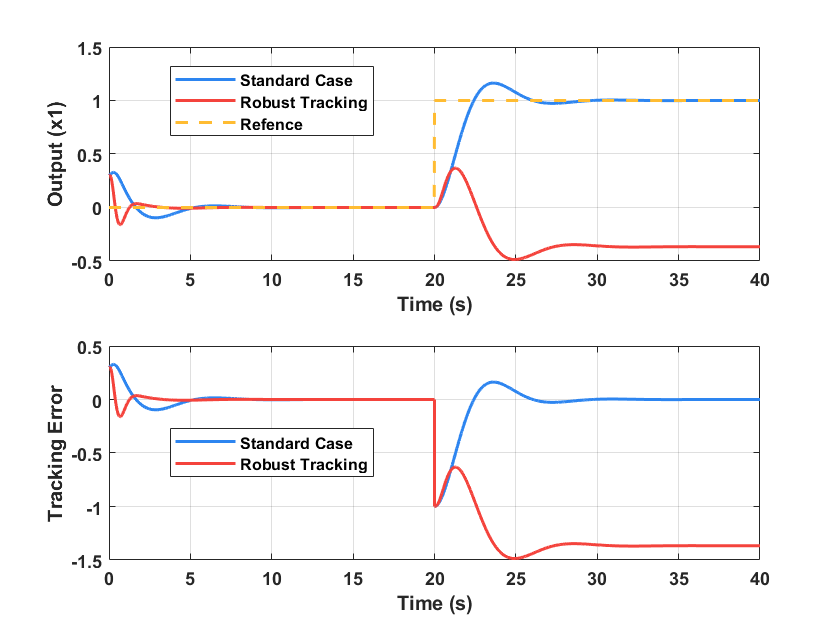

rFlag = 1;
wFlag = 0;
sim('model4_RobustTracking.slx')

figure
subplot(2,1,1)
plot(t,[x1(:,1) x2(:,1)])
hold on
grid on
plot(t,r,'--')
legend('Standard Case','Robust Tracking','Refence','Location','best')
xlabel('Time (s)')
ylabel('Output (x1)')
subplot(2,1,2)
plot(t,[x1(:,1)-r x2(:,1)-r])
grid on
legend('Standard Case','Robust Tracking','Location','best')
xlabel('Time (s)')
ylabel('Tracking Error')

此时鲁棒跟踪设计的输出不能实现信号的跟踪，这是因为阶跃响应不满足参数设计时假设的参考信号的微分方程。

## 结论

综上所述，我们可以得到以下结论：

- 直接在控制信号引入参考信号的方式较为普适，但可能会因为系统的响应延时导致跟踪误差；

- 若参考信号的微分方程已知，利用鲁棒跟踪的设计能够使跟踪误差收敛到零，但这种方法不具有普适性，不同的参考信号需要单独进行设计；

- 鲁棒跟踪控制不仅能使系统输出跟随参考信号，还能抑制被控对象中存在的同类扰动。